- Initialize  for example $\delta =\left\lbrack -15,-10,-5,\;0,5,10,15\right\rbrack$*, *$f_{\textrm{dri}} =1$*, *$f_{\textrm{brk}} =0$*;*

- choose $\textrm{dt}=0\ldotp 1$, calculate path $x=x+\left(\dot{\;x} \;\textrm{dt}\right)$,      there are total $n=\;\textrm{length}\left(\delta \;\right)$ paths

- determine $f_{\textrm{dri}}$ based on $v=v+\frac{\left(f_{\textrm{dri}} +f_{\textrm{brk}} -f_{\textrm{drag}} \right)}{m\;}\textrm{dt}$

- Does the $\delta \;$need to be updated based on curvature?

- **How to decide the next intputs?**

clear all;
%close all;


Define sample time

Discretzie steer angle;

dt= 0.1; % stepwise
t_list= (0:dt:3)'; % total time
u_steer_dis= deg2rad((-15:1:15)');


Calculate  $\dot{s} =\frac{v\cdot \mathrm{cos}\left(\beta -\xi \right)}{1-n\cdot \kappa }$

u_table= readtable('ctrl_inputs.csv');

x_table= readtable('states.csv');
kappa_opt_table= readtable('kappa_opt.csv');

s_opt_table= readtable('length_opt.csv');


beta= x_table.Var2;
n= x_table.Var4;
xi= x_table.Var5;
kappa= kappa_opt_table.x_Kappa_opt;

sdot= cos(beta- xi)./(1-n.*kappa);

s_cum= cumsum(s_opt_table.x_S_opt);
ds_opt= s_opt_table.x_S_opt;

sim_length= 1:5;

Initilize the states;

Call StateUpdate function to calcuate the path for each steer inputs

state0= [-0.08855;0.8886;0;0.01];
[state, u_tmp] = StateUpdate_ds(state0, u_steer_dis, s_cum(sim_length), ds_opt(sim_length), sdot(sim_length));

path_og_table= readtable('track_smooth.csv');

path_opt_table= readtable('traj_opt.csv');

s_og_table= readtable('length_center.csv');

london_outer_table=readtable('london_outer.csv');

london_inner_table=readtable('london_inner.csv');

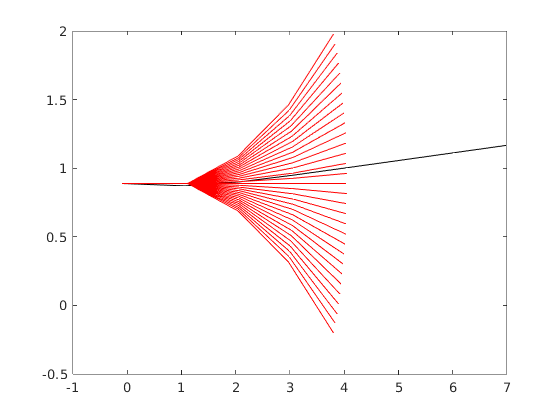

close all;
plot_num= 1:8;
figure()
plot(path_opt_table.x_Traj_x(plot_num), path_opt_table.traj_y(plot_num), 'color', 'black');
hold on;
% plot(london_outer_table.x_X, london_outer_table.y, 'blue', 'LineWidth', 1.0)
% hold on;
% plot(london_inner_table.x_X, london_inner_table.y, 'blue','LineWidth', 1.0)
% hold on;
for j= 1:length(s_cum(sim_length)):length(state)
    plot(state(1,j:j+length(s_cum(sim_length))-1), state(2,j:j+length(s_cum(sim_length))-1), 'color', 'red');
    hold on;
end


% figure()
% plot_num= 1:940;
% plot(path_opt_table.x_Traj_x(plot_num), path_opt_table.traj_y(plot_num))
% hold on
% plot(path_og_table.x_Track_x(plot_num), path_og_table.track_y(plot_num), 'red', 'LineStyle',"--")
% hold on;
% plot(london_outer_table.x_X, london_outer_table.y, 'red', 'LineWidth', 1.0)
% hold on;
% plot(london_inner_table.x_X, london_inner_table.y, 'red','LineWidth', 1.0)
% hold off;
% grid on; grid minor;
% text(0,0,'|','color', 'black')
% legend('opt path', 'center line', "Location", 'Northeast')
% xlabel('x(m)');
% ylabel('y(m)');
% title('Path')